# parpool Introduction

The purpose of this excercise is to learn what is a parallel pool and the different ways to start and shut it down.

To get started, run the following.

doc parpool

## Start a parallel pool programmatically

Start an interactive parallel pool of 2 workers through the command line.

% TODO: Start an interactive parallel pool of 2 workers programatically
parpool(2)

Starting parallel pool (parpool) using the 'Processes' profile ...
09-Sep-2025 13:38:03: Job Queued. Waiting for parallel pool job with ID 1 to start ...
Connected to parallel pool with 2 workers.

ans = 

 ProcessPool with properties: 

            Connected: true
           NumWorkers: 2
                 Busy: false
              Cluster: 

What happens if you try to run the above command a second time?

Only one interactive parallel pool can be open at a time.

## Start a parallel pool interactively

*Hint*: Look at the bottom left corner of the MATLAB desktop.

The pool status indicator in the lower-left corner of the desktop shows the client connection to the pool and the pool status. (*Note the parallel status indicator is not visible by default in MATLAB Online. You must start a parallel pool first by using *[`parpool`](https://www.mathworks.com/help/parallel-computing/parpool.html)* or any of the functions that automatically start a parallel pool*.)

With a pool running: 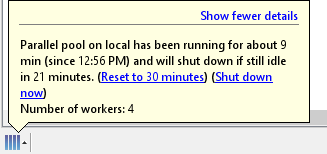

With no pool running: 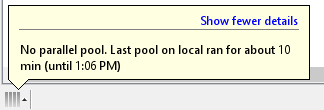

With default preferences, MATLAB starts a pool on the local machine with one worker per physical CPU core, up to the preferred number of workers. 

## Shutdown the parallel pool

*Hint*: Look at [`gcp`](https://www.mathworks.com/help/parallel-computing/gcp.html) to get a handle to the parallel pool object and [`delete`](https://www.mathworks.com/help/parallel-computing/parallel.pool.delete.html)

% TODO: Programmatically delete the interative pool
p = gcp


p = 

 ProcessPool with properties: 

            Connected: true
           NumWorkers: 2
                 Busy: false
              Cluster: 

delete(p)

Parallel pool using the 'Processes' profile is shutting down.


What other ways can the parallel pool be shutdown?

Interactive pool status indicator in bottom left.

*Copyright 2025 The MathWorks, Inc.*